data1 = readmatrix("data_positive_U_I.txt");
U_positive=data1(:,1);
I_positive=data1(:,2);

figure(1)
plot(I_positive,U_positive, 'r');
title("U_c_t_r_l(I) - positive")
xlabel("I, A")
ylabel("U_c_t_r_l, V")
hold on

R0 = [0.6];

func = @(R,I) R(1)*I;
% Nonlinear least-squares solver %
solver = lsqcurvefit(func,R0,I_positive,U_positive);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


## Судя по методичке, всё расчеты надо было проводить раздельно для отрицательных-позитивных значений

##  -> ввёл разделение на positive-negative соответственно

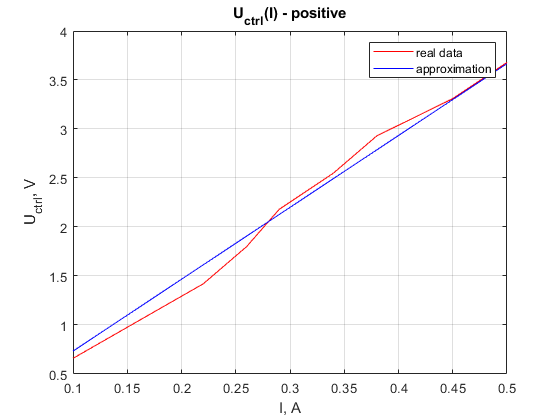

new_R_1 = solver(1);

plot(I_positive,new_R_1*I_positive,'b');
legend('real data', 'approximation');
grid on




figure(2)
data2 = readmatrix("data_negative_U_I.txt");
U_negative=data2(:,1);
I_negative=data2(:,2);
plot(I_negative,U_negative,'b');
title("U_c_t_r_l(I) - negative")
xlabel("I, A")
ylabel("U_c_t_r_l, V")
grid on

hold on
top1 = 0;
bottom1 = 0;

bottom1 = 0

for i=1:9
    top1 = top1 + (U_negative(i) * I_negative(i));
    bottom1 = bottom1+ I_negative(i)^2;
end
top2 = 0;
bottom2 = 0;
for i=1:9
    top2 = top2 + (U_positive(i) * I_positive(i));
    bottom2 = bottom2 + I_positive(i)^2;
end


R_final_alternative = ((top2/bottom2)+(top1/bottom1))/2

R_final_alternative = 7.5865


R0 = [0.9];

func = @(R,I) R(1)*I;
% Nonlinear least-squares solver %
solver = lsqcurvefit(func,R0,I_negative,U_negative);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


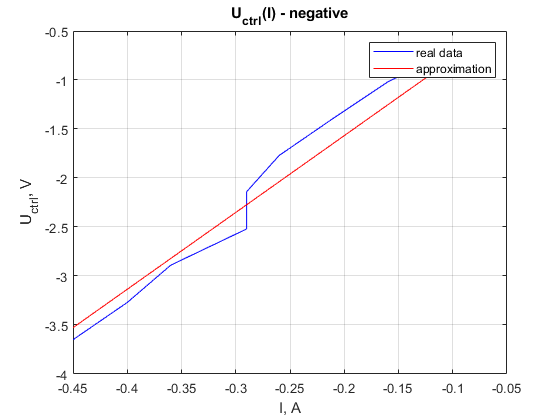

new_R_2 = solver(1);

plot(I_negative,new_R_2*I_negative,'r');
legend('real data', 'approximation');

Mean value: (R1+R2)/2

R_final = (new_R_1 + new_R_2)/2

R_final = 7.5865

### Moment of inertia from 1st lab  and Inductance

J = 0.0023;
L = 0.0047;


files = ["data-10", "data-15", "data-20", "data-25", "data-30", "data-35", "data-40", "data-45", "data-50", "data10", "data15", "data20", "data25", "data30", "data35", "data40", "data45", "data50"];
% in percents of maximum %
voltages = [-10, -15, -20, -25, -30, -35, -40, -45, -50, 10, 15, 20, 25, 30, 35, 40, 45, 50];
k_all = [];
Tm_all = [];
omega_final_positive = [];
omega_final_negative = [];
for i=1:9
    % время градус_поворота угловая_скорость %
    data = readmatrix(files(i));
    time=data(:,1);
    U = voltages(i);
    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    coef = [0.1; 0.06];
    func = @(lol, time) U*lol(1)*(1 - exp(-time/lol(2)));
    
    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,coef,time,omega);
    k = solver(1)
    Tm = solver(2);
    
    time_apr = 0:0.01:1;
    omega_final_negative(i) = U*k;
    
    
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.0928


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1057


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1116


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1151


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1165


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1177


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1180


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1176


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


k = 0.1177

for i=10:18
    % время градус_поворота угловая_скорость %
    data = readmatrix(files(i));
    time=data(:,1);
    U = voltages(i);
    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    coef = [0.1; 0.06];
    func = @(lol, time) U*lol(1)*(1 - exp(-time/lol(2)));
    
    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,coef,time,omega);
    k = solver(1);
    Tm = solver(2);
    
    time_apr = 0:0.01:1;
    omega_final_positive(i-9) = U*k;    
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

omega_final_positive

omega_final_positive =     0.9284    1.6298    2.2939    2.9542    3.6143    4.2757    4.8877    5.4956    6.0907


omega_final_negative

omega_final_negative =    -0.9284   -1.5853   -2.2312   -2.8773   -3.4951   -4.1181   -4.7188   -5.2921   -5.8869



figure(4)
title("U(omega_f_i_n_a_l) - negative ")
plot(omega_final_negative,U_negative, 'b');
legend('real data', 'approximation');
xlabel("angle speed, rad/s")
ylabel("U, V")
hold on
coef = [0.1];
U_func = @(k_e,w_final) k_e*w_final;
solver = lsqcurvefit(U_func,coef,omega_final_negative,transpose(U_negative));


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


new_k_e_negative = solver(1)

new_k_e_negative = 0.6172

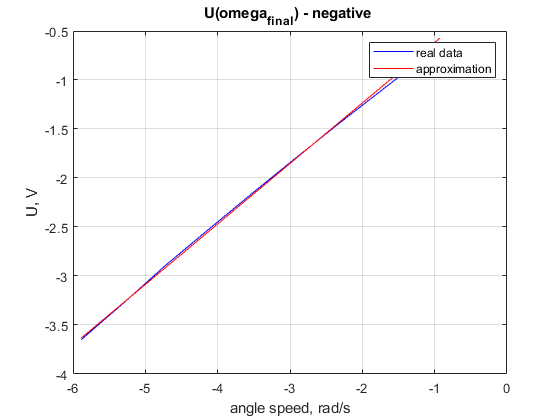


plot(omega_final_negative,new_k_e_negative*omega_final_negative, 'r');
legend('real data', 'approximation');
grid on

figure(5)
title("U(omega_f_i_n_a_l) - positive ")
plot(omega_final_positive,U_positive,'g');
legend('real data', 'approximation');
xlabel("angle speed, rad/s")
ylabel("U, V")
hold on
coef = [0.1];
U_func = @(k_e,w_final) k_e(1)*w_final;
solver = lsqcurvefit(U_func,coef,omega_final_positive,transpose(U_positive));


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


new_k_e_positive = solver(1)

new_k_e_positive = 0.6040

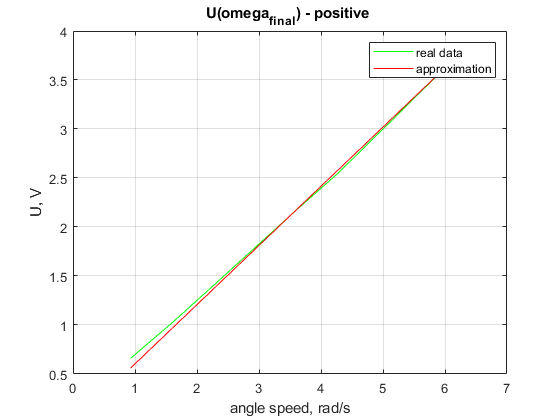


plot(omega_final_positive,new_k_e_positive*omega_final_positive, 'r');
grid on
legend('real data', 'approximation');

k_m = (new_k_e_positive + new_k_e_negative)/2 

k_m = 0.6106

### Сравнение с моделью симулинка

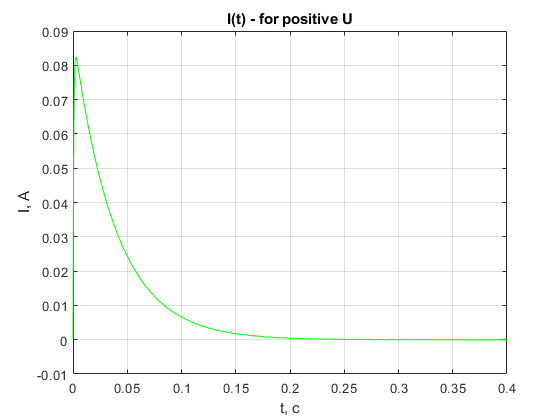

figure(6)
plot(out.I.Time,out.I.Data,'g');
title("I(t) - for positive U")
xlabel("t, с")
ylabel("I, A")
grid on